## RNA Folding Using Genetic Algorithms

bmes.diskusage

Your folder [ C:/ahmet/course/sim2/webdata/moleculardynamics/rnafoldga_demo/ ] is using [[ 0.9 MB ]] of disk space.
--- NOTICE: at sys_cdif.m:6, sys_cdhere.m:4, diskusage.m:58, LiveEditorEvaluationHelperE722410233.m:1 : 
Changing directory to: C:\ahmet\course\sim2\webdata\moleculardynamics\rnafoldga_demo


if isempty(which('ga')); error('It appears that you do not have the ga() function available. You need to install the Global Optimization Toolbox. You can do that using Add-Ons menu in Matlab.'); end

rna = readtable('1c0a.tab','filetype','text')

rna = 68×4 table
    base       x         y         z   
    _____    ______    ______    ______

    {'G'}    44.581    17.614    -1.427
    {'G'}    47.287    12.978    -3.603
    {'A'}    52.399    10.556    -3.857
    {'G'}    57.803     9.677    -2.093
    {'C'}    62.005    10.493     1.508
    {'G'}     63.72    12.271     6.688
    {'G'}    62.823     14.05    12.343
    {'A'}    59.694    16.974    21.949
    {'G'}    57.787    19.991    27.067
    {'U'}    58.333    23.168    22.262
    {'U'}    61.837    24.036    17.815
    {'C'}    66.025    20.657    14.909
    {'A'}    69.591    15.896    13.591
    {'G'}    70.988    10.161    13.946
    {'C'}    71.429     0.461    11.265
    {'G'}    65.791    -2.886    11.501


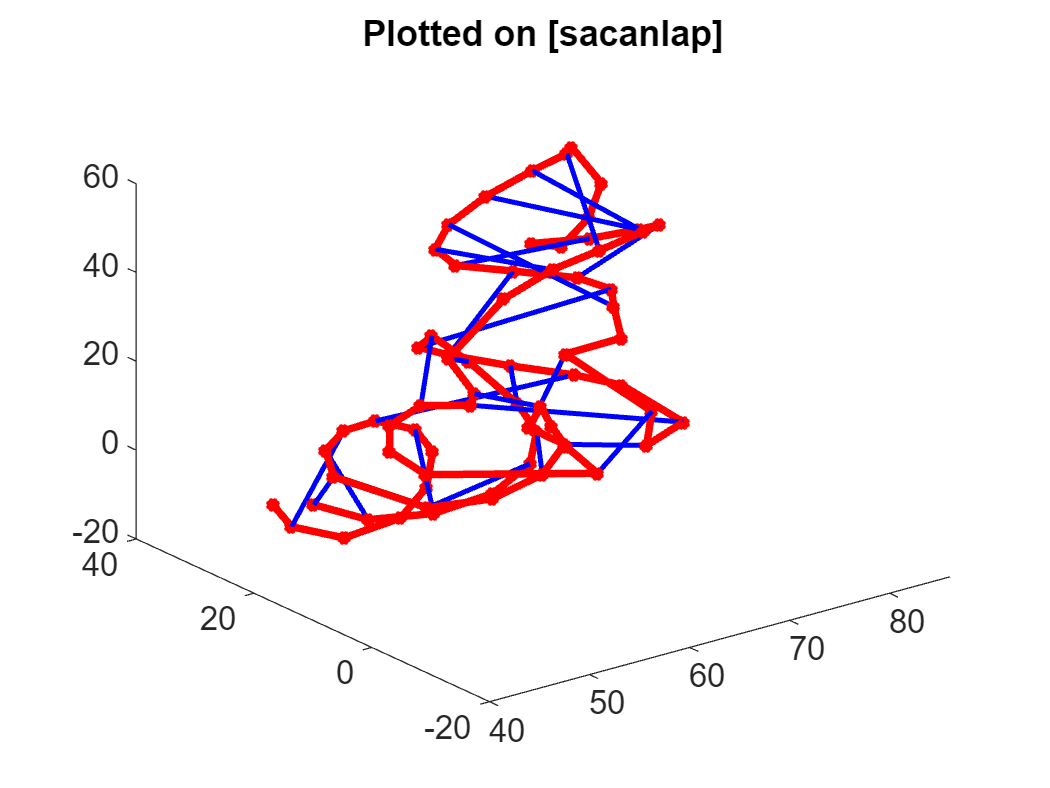

seq = rna{:,'base'}; seq=[seq{:}];
locs = rna{:,{'x','y','z'}};
pairs = rna_gethydrogenbondedpairs(seq,locs);
rna_plot(locs,pairs);

[fitness,info] = rna_fitness( seq, locs )

fitness = 52.7488

info = struct with fields:
       seqviolations: 14.2512
    nonseqviolations: 0
         totalhbonds: 67


options = optimoptions('ga','PlotFcn', @gaplotbestf,'UseParallel',true)  %You can add options when calling this, or later modify options variable.

options =   ga options:

   Set properties:
                         PlotFcn: @gaplotbestf
                     UseParallel: 1

   Default properties:
             ConstraintTolerance: 1.0000e-03
                     CreationFcn: []
                    CrossoverFcn: []
               CrossoverFraction: 0.8000
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
               FunctionTolerance: 1.0000e-06
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
                  MaxGenerations: '100*numberOfVariables'
             MaxStallGenerations: 50
                    MaxStallTime: Inf
                         MaxTime: Inf
                     MutationFcn: []
    Non

problem = struct('nvars',numel(seq)*3, 'fitnessfcn', @(v)-rna_fitness(seq,v),'solver','ga', 'options',options);
galocs = ga(problem);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


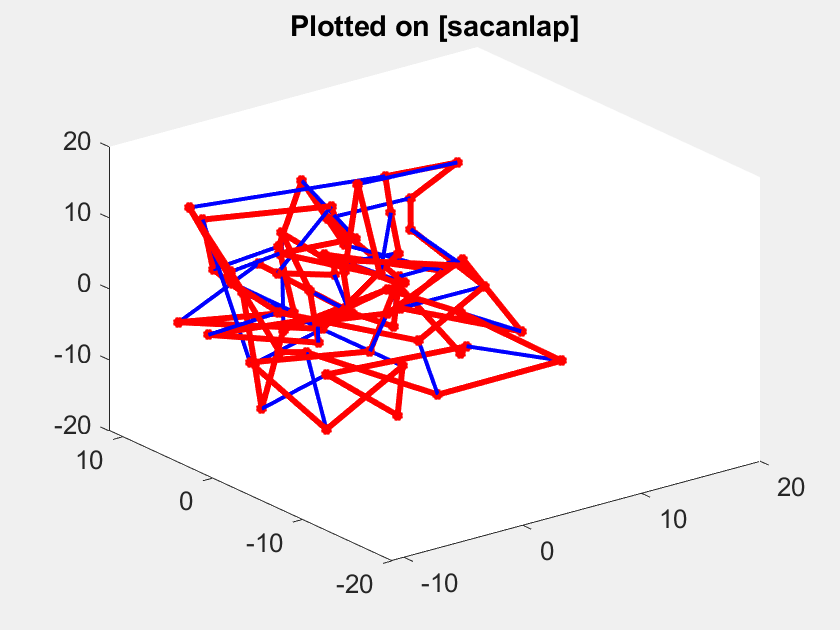

rna_plot(galocs,rna_gethydrogenbondedpairs(seq,galocs));

### Use a custom Cross-over function

problem.options.CrossoverFcn=@rnafoldga_crossover;
galocs = ga(problem);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


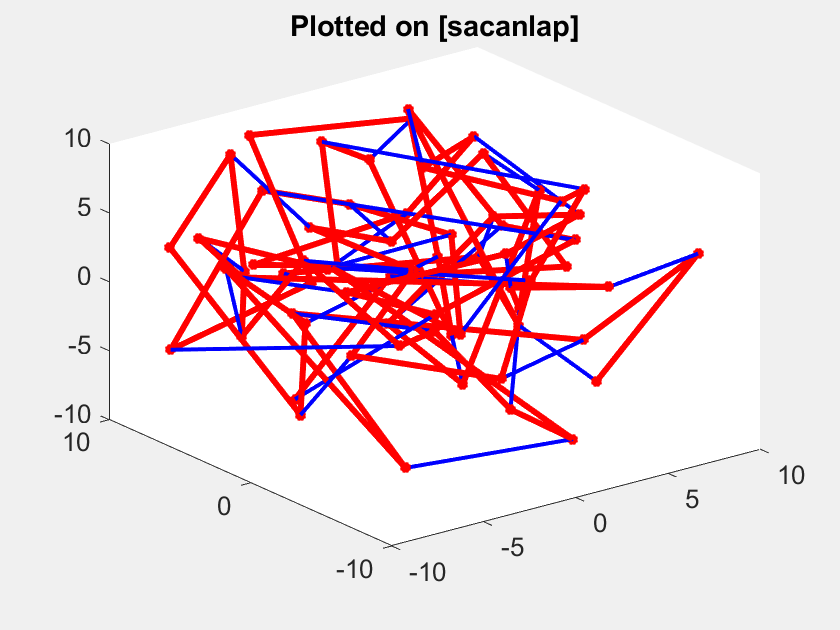

rna_plot(galocs,rna_gethydrogenbondedpairs(seq,galocs));

[fitness,info] = rna_fitness( seq, galocs )

fitness = -12.8339

info = struct with fields:
       seqviolations: 43.7257
    nonseqviolations: 55.1082
         totalhbonds: 86
